# Channel Estimation and Basic Adaptive Filtering

## 1 SYSTEM MODEL AND GENERATION OF TRANSMITTED SIGNAL AND MODELLING THE CHANNEL

%%unknown channel model 

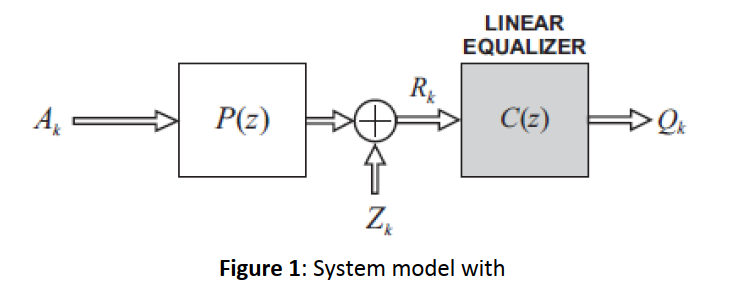

### 1.2 SYSTEM PARAMETERS AND TRANSMITTED SEQUENCE GENERATION 

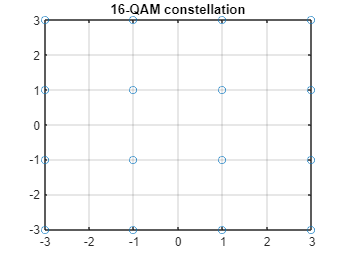

close all
clear all
clc
SNR = 15; %Signal to noise ratio 
Rs = 20e6; %Let's define symbol rate for the plotting purposes 
a = repmat(-3:2:3,1,4)-[repmat(-3j,1,4) repmat(-1j,1,4) repmat(1j,1,4) repmat(3j,1,4)]; 
Ak = a(randi(16,1000,1)); % 16-QAM sequence of 1000 samples
figure(1); plot(real(a),imag(a),'o'); title('16-QAM constellation'); grid;

## 1.3 BASEBAND EQUIVALENT SYSTEM MODEL

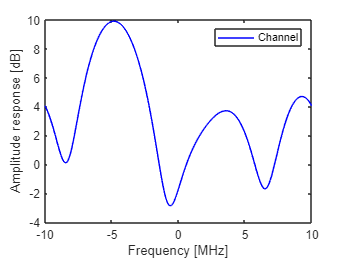

%% Channel creation and channel modelling 
p = [0.19+.56j .45-1.28j -.14-.53j -.19+.23j .33+.51j]; % Example complex channel model 
L1=1; % Channel maximum tap is the second one
%Plotting amplitude response of the channel: 
figure(2); [H,f]=freqz(p,1,-Rs/2:Rs/200:Rs/2,Rs); plot(f/1e6,20*log10(abs(H)),'b'); 
xlabel('Frequency [MHz]');ylabel('Amplitude response [dB]'); legend('Channel'); 

### 1.4 APPLYING THE CHANNEL AND NOISE TO THE TRANSMITTED SEQUENCE

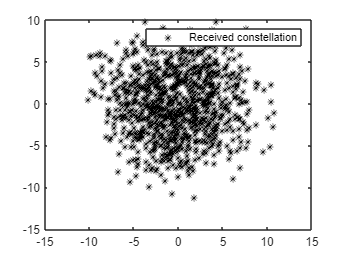

Rk = filter(p,1,Ak); % Received signal 
Rk = Rk(L1+1:end); % Discard the delay, if channel has pre-cursor taps

noise = (1/sqrt(2))*(randn(size(Rk)) + 1j*randn(size(Rk))); %Initial noise vector 
P_s = var(Rk); % Signal power 
P_n = var(noise); % Noise power 
% Defining noise scaling factor based on the desired SNR: 
noise_scaling_factor = sqrt(P_s/P_n./10.^(SNR./10)); 
Rk_noisy = Rk + noise*noise_scaling_factor; % Received signal 

figure(1); plot(Rk,'*k'); legend('Received constellation');

## 2 CHANNEL ESTIMATION 

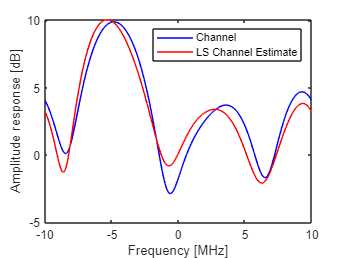

M = 30; %number of reference symbols used for channel estimation; this is pretty small amount 
estimate_length = 7; %this defines how long is the channel estimate's impulse response 
A_conv=convmtx(Ak(2:M+1).',estimate_length); % Convolution matrix 
p_LS=((A_conv'*A_conv)\(A_conv'))*Rk_noisy(1:size(A_conv,1)).'; % LS solution

figure(2); hold on; [H,f]=freqz(p_LS,1,-Rs/2:Rs/200:Rs/2,Rs); 
plot(f/1e6,20*log10(abs(H)),'r'); legend('Channel','LS Channel Estimate');

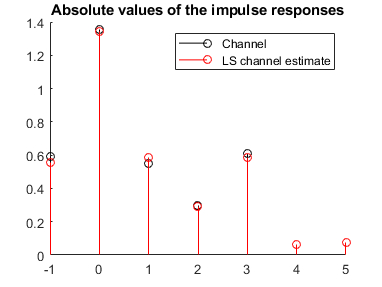


figure(3); hold on; stem(-L1:length(p)-L1-1,abs(p),'k'); 
stem(-L1:length(p_LS)-L1-1,abs(p_LS),'r'); 
legend('Channel','LS channel estimate'); 
title('Absolute values of the impulse responses');

## 3 DESIGN OF CHANNEL EQUALIZER WITH MINIMUM MSE CRITERION AND WITH ADAPTIVE LMS ALGORITHM

### 3.1 MMSE CHANNEL EQUALIZATION 

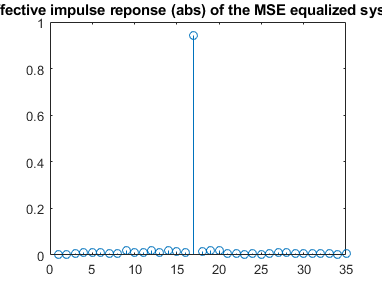

%% MSE Equalizer (example with 10000 training symbols) 
% Initialization 
FII = zeros(31,31); % Autocorrelation Matrix initialization 
alfa = zeros(31,1); % Cross-correlation vector initialization 
% Estimating FII and alfa using sample estimates based on training symbols 
% Notice that here we use all the generated data as training symbols 
for i = 16:length(Rk_noisy)-15, 
    rk = flipud(Rk_noisy(i-15:i+15).'); % Received signal vector 
    FII = FII + rk*conj(rk).'; % Autocorrelation matrix 
    alfa = alfa + Ak(i)*conj(rk); 
end 
FII = FII/(length(Rk_noisy)-30); % Final sample estimate of the autocorrelation matrix 
alfa = alfa/(length(Rk_noisy)-30); % Final sample estimate of the cross-correlation vector 
c_MSE = inv(conj(FII))*alfa; % Equalizer coefficients 

figure(4); stem(abs(conv(p,c_MSE)));
title('Effective impulse reponse (abs) of the MSE equalized system') 

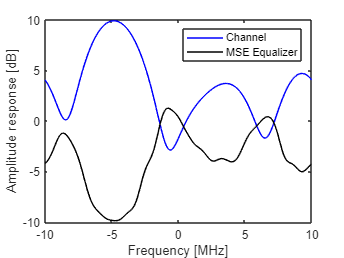

figure(5); [H,f]=freqz(p,1,-Rs/2:Rs/200:Rs/2,Rs); plot(f/1e6,20*log10(abs(H)),'b'); 
xlabel('Frequency [MHz]');ylabel('Amplitude response [dB]'); 
figure(5); hold on; [H,f]=freqz(c_MSE,1,-Rs/2:Rs/200:Rs/2,Rs); 
plot(f/1e6,20*log10(abs(H)),'k'); 
legend('Channel','MSE Equalizer'); 

### 3.2 DESIGN OF CHANNEL EQUALIZER USING LMS ALGORITHM

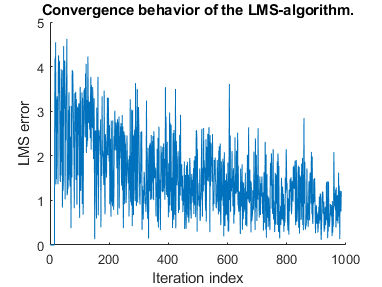

beta = 0.0001; % step-size of the algorithm 
c_LMS = zeros(31,1); % equalizer coefficients, initializations 
for i = 16:length(Rk_noisy)-15 
    rk = flipud(Rk_noisy(i-15:i+15).'); % Received signal vector 
    Ek(i) = Ak(i) - c_LMS.'*rk; % Error signal, we assume a known symbol sequence 
    c_LMS = c_LMS + beta*Ek(i)*conj(rk); % LMS update ! 
end 
 
figure(6); hold on; plot(abs(Ek)); title('Convergence behavior of the LMS-algorithm.'); 
ylabel('LMS error'); xlabel('Iteration index'); 

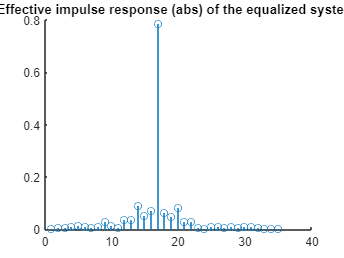

figure(7); hold on; stem(abs(conv(p,c_LMS))); 
title('Effective impulse response (abs) of the equalized system ') 

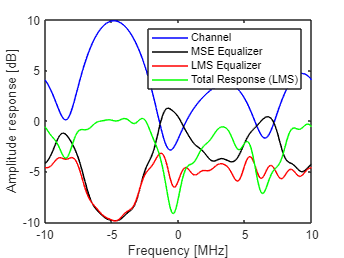

figure(5); hold on; [H,f]=freqz(c_LMS,1,-Rs/2:Rs/200:Rs/2,Rs); 
plot(f/1e6,20*log10(abs(H)),'r'); 
[H,f]=freqz(conv(c_LMS,p),1,-Rs/2:Rs/200:Rs/2,Rs); 
plot(f/1e6,20*log10(abs(H)),'g'); 
legend('Channel','MSE Equalizer','LMS Equalizer','Total Response (LMS)'); 

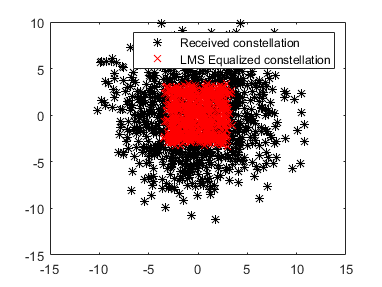

 
figure(1); hold on; plot(filter(c_LMS,1,Rk),'rx'); 
legend('Received constellation','LMS Equalized constellation')